# TITLE

Emma King, Ryan McGee, Audrey Tomko

*VIDEO LINK HERE*

## Introduction

In the realm of hydrology and hydraulics, understanding the dynamics of water flow in open channels is essential for effective water resource management. Globally, flooding remains a pervasive and destructive natural disaster, resulting in substantial property damage and loss of life (Mujumdar, 2001). This study seeks to contribute significantly by constructing a hydrodynamic model to predict flood wave propagation in natural rivers, employing the Saint Venant equations. The development of predictive models holds great promise for mitigating the impact of future flooding, thereby preventing loss of life and property. Accurate estimations of floods and an in-depth comprehension of how stream channels influence flooding dynamics are vital for designing effective protective structures (Keskin, 1997).

At the core of this modeling effort are the Saint Venant's equations, which consist of a continuity equation and a momentum equation. While these equations have been previously modeled using various techniques, common approaches often involve simplifications to the full momentum equation. Techniques such as kinematic wave routing (Agiralioglu, 1981) and diffusion approximation (Aken and Yen, 1981) have been explored, but concerns persist regarding the accuracy of these simplified models (Keskin, 1997). However, such models typically demand significant computational effort, highlighting a trade-off between accuracy and computational efficiency. In essence, this project delves into the modeling of flood wave propagation using Saint Venant's equations, offering nuanced insights into a critical aspect of hydrodynamic research while adopting a rectangular cross-section approach.

## Equations

### Fundamental Physical Process and Derivation of Equations

The fundamental physical processes being explored are the hydraulic and hydrologic behavior in bodies of water, specifically, flood wave propagation in natural rivers. The Saint Venant’s equations are the basic equations that describe wave propagation in an open channel. While there are also 2-dimensional versions of these equations, the 1-dimensional Saint Venant’s equations describe flood mechanics and are used to build this model. There are two main equations: 

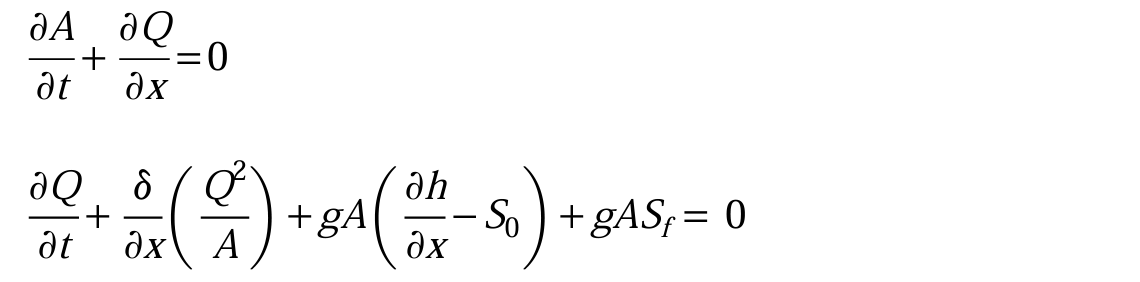

Equation 1 is the continuity equation, which expresses the conservation of water volume. Equation 2 is the momentum equation, which provides the balancing between forces and momentum change rates. To create this model, another form of the momentum equation was derived using equations 1, 2, and 3:

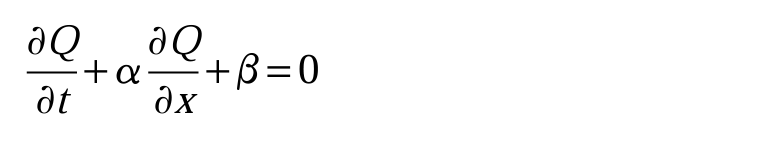

Where,

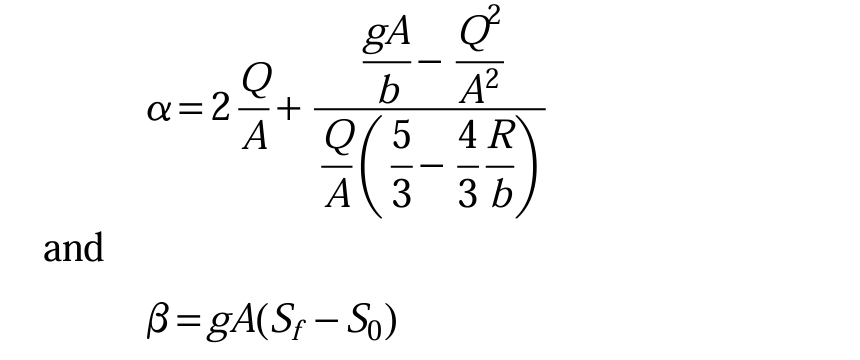

### Boundary and Initial Conditions

#### *Initial conditions:*

#### *Boundary conditions:*

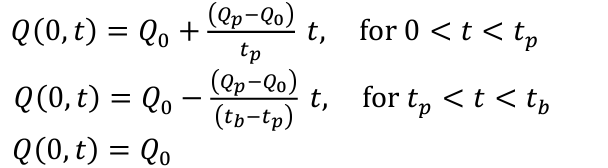

### Simplifications and assumptions

- Flow is considered 1-Dimensional

- Distribution of pressure vertically is hydrostatic

- Water is incompressible and homogenous

- Density is constant through time and space

- The shape of the channel is a rectangle and constant

- h (surface level of water in the channel) = 3.5 meters

## Numerical Methods

#### *Utilizing the Advection Method with an Upwind Scheme to Model Flood Propogation.* 

Modelling hydodynamic properties is no easy task. The advection method is used because of the complexity of our theoretical river system. With numerous variables and the desire to show how small changes impact flow on a larger scale, it accomplishes exactly what we want.

Parameters like the slope of the river, river shape, friction, and velocity all impact how this scenario could play out in the real-world, offering valuable insights into the system's response to alterations in the river's geometric and hydraulic characteristics. This is important on a larger scale as the model is dealing with trying to understand how flood waves propogate in a river system.

After defining our parameters, we set up initial conditions and boundary conditions for discharge (Q) and cross-sectional area (A) matrices. We then iteratively solves the Saint-Venant equations, which describe one-dimensional open channel flow, using finite difference methods. The hydraulic radius (R), advection coefficient (alpha), and source term (beta) are calculated at each spatial location and time step. The Courant value is monitored for stability.

The results are plotted to visualize the inflow and cross sectional discharge at different distances along the channel over time (Figure 1), along with varying paramters (Figure 2,3,4).

## **CODE**

### Simulation 1: Inflow hydrograph and computed outflow hydrographs at different distances

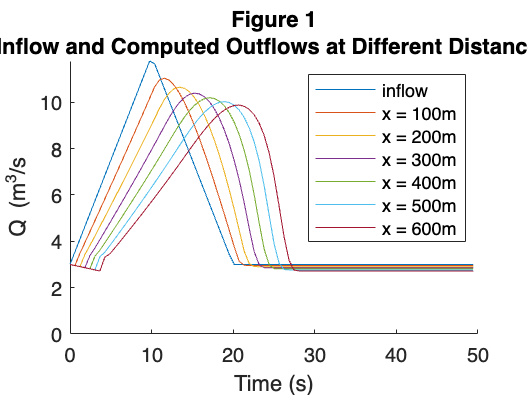

%parameters:
L = 2000; %length of channel, meters(m)
b = 5; %width of the bottom of the channel, meters(m)
S0 = 0.0005; %slope of the bottom of the channel
n = 0.0138; %Manning's roughness coefficient for the bottom of the channel
g = 9.8; %acceleration due to gravity, (m^2/s)
h = 3.5; %water depth, meters(m)

%set up time and space vectors
dt = 0.61; % delta t, seconds (s)
t = 0:dt:50; %time vector
dx = 100; % delta a, meters (m)
x = 0:dx:L; %space vector

%pre-allocate Q matrix and A matrix
Q = zeros(length(x), length(t));
A = ones(length(x), length(t));

%set up initial/boundary conditions for Q and A
Q0 = 3; %base flow of inflow hydrograph, m^3/s
Qp = 12; %peak flow of inflow hydrograph, m^3/s
tp = 10; %time to peak flow of inflow hydrograph, seconds
tb = 20; %total time to return to base flow after peak flow
mask = t < 10;
Q(1,mask) = Q0 + ((Qp-Q0)/(tp))*t(mask);
Q(:, 1) = Q0;
mask = t >= 10 & t < 20; 
Q(1,mask) = Q0 - ((Qp-Q0)/(tb-tp))*(t(mask)-tb);
mask = t >= 20;
Q(1,mask) = Q0;

A(:,1) = b*h; %inital cross section area calculated from given width and estimated water depth of channel, meters (m)

% matrix with the same dimensions to keep track of Courant value. 
C = zeros(length(x), length(t));

%solve the equations
for j = 1:length(t)-1
    for i = 2:length(x)-1 

        R = A(i,j)/(2*h+b); %R is the hydraulic radius
        alpha = 2*(Q(i,j)/A(i,j)) + (((g*A(i,j))/b)+(Q(i,j)/A(i,j))^2)/((Q(i,j)/A(i,j))*((5/3)-(4/3)*(R/b)));
        beta = g*A(i,j)*(((Q(i,j)^2*n^2)/(A(i,j)*R^(4/3)))-S0);
        
        C(i,j) = (dt/dx) * alpha; %need to keep values below but close to 1 to remain stable

        Q(i, j+1) = Q(i,j) - (dt/dx) * alpha * (Q(i,j)-Q(i-1,j)) + beta*dt;
        A(i, j+1) = A(i,j) - (dt/dx) * (Q(i, j)-Q(i-1,j));
    end
end

%plot inflow and outflow
figure
hold on
for y = 1:7
    plot(t,Q(y,:));
end
ylim([0, inf])
xlabel('Time (s)')
ylabel('Q (m^3/s')
legend('inflow', 'x = 100m', 'x = 200m', 'x = 300m', 'x = 400m', 'x = 500m', 'x = 600m')
title(["Figure 1", "Inflow and Computed Outflows at Different Distances"])



% conservation of mass
mass = sum(Q,2); %total amount of water at each position, x
notConserved = mass(1)-mass(end-1); %total amount of mass lost in the model


### Simulation 2: Unstable Figure 1

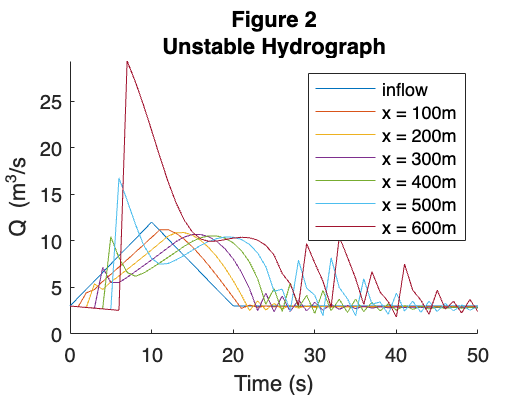

[Qu, tu] = waveProp(0.0005, 0.0138, 1);

figure;
hold on
for y = 1:7
    plot(tu,Qu(y,:));
end
ylim([0, inf]);
xlabel('Time (s)');
ylabel('Q (m^3/s');
legend('inflow', 'x = 100m', 'x = 200m', 'x = 300m', 'x = 400m', 'x = 500m', 'x = 600m');
title(["Figure 2", "Unstable Hydrograph"])

### *Discussion*

The first simulation we ran plotted discharge, Q, over time, for different positions along the channel using the paramaters, boundary conditions, and inital values of the triangular inflow hydrograh from Keskin, 1997. We knew that dx needed to be sufficiently small to ensure stability, and dt/dx needed to be smaller than the Courant criteria. For the simple advection equation C = u*(dt/dx), where u is a constant and because we want C to be less than or equal to 1, the time step can be determined based on the desired Courant criteria. For our equation, C = α*(dt/dx), but α changes at every step, which means that C is also changing at every step. Because of this, the time step cannot be determined based on setting a value for C to ensure stability. We started with dt= 1, rather than the suggested dt=10, hoping that would be small enough but as can be seen in Figure 2, even a dt of 1 was still unstable. In order to determine the best time step, we considered the general trend of the matrix of Courant values and conservation of mass throughout the model. The Courant values needed to all be as close as possible to 1 while still being less than 1. In a perfect model, there would be the same amount of mass present the whole time Our model is not perfect and the smallest amount of mass loss or gain we could find was 1.555 when the time step was 0.61. This is the time step used to create Figures 1, 3, and 4. 

Figure 1 models a flood wave propagating along a channel by calculating and graphing values of Q over time at different points along the channel. Figure 2 attempts to do the same thing but fails due to instability in the model. The results of Figure 1 are similar to figure 3 in (Sulistyono and Wiryanto, 2017):

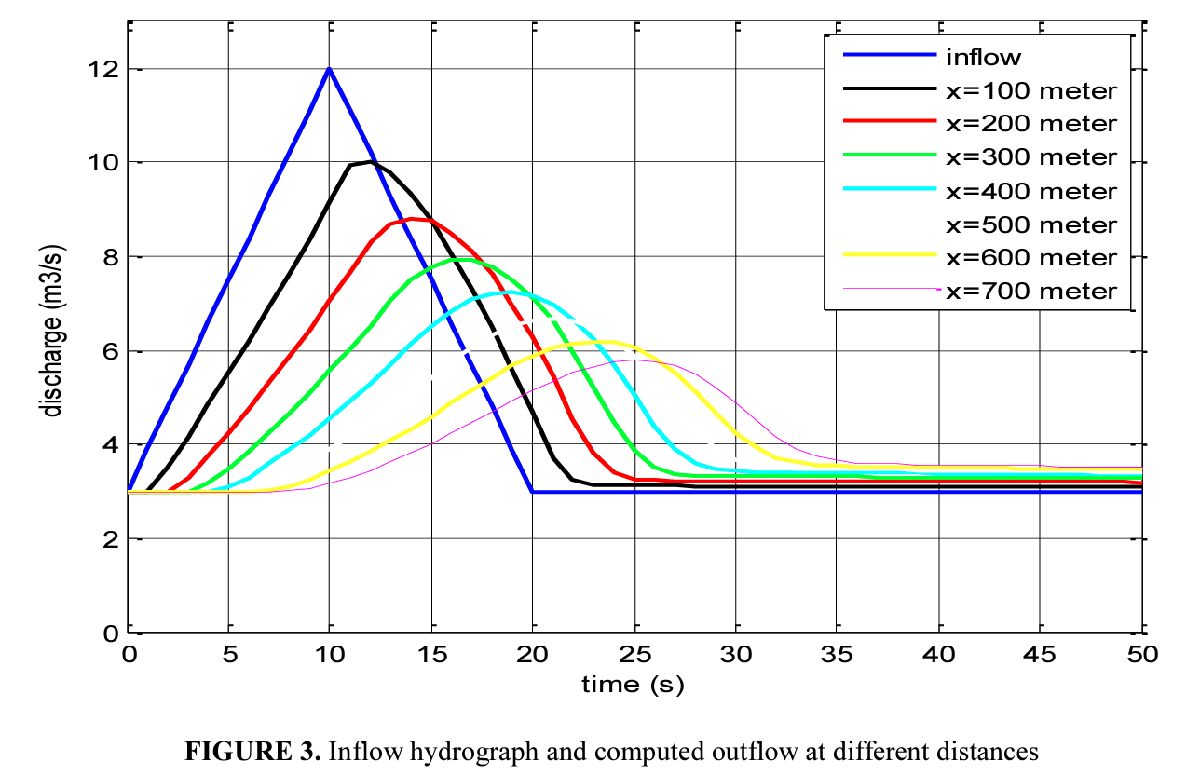

While their shapes are similar there are some important differences. First, the Sulistyono and Wiryanto, 2017 figure was modeled using a trapezoial channel rather than the rectangular channel used in our model. There is also some remaining instability in the beginning of our model, as Q dips below its boundary condition of Q = 3 m^3/s in the beginning of the wave propagation, and returns to steady state below its condition of Q0 = 3 m^3/s. Our attempts to fix these issues were not successful and it is likely that a different BLAH BLAH BLAH

*How do the results compare with any known solutions, or data?*

*How do the results change with different methods, time steps, grid spacing, or model parameters?*

### Simulation 3: Variation of S0

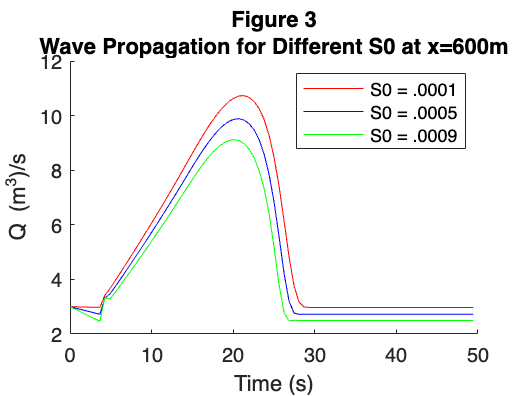

QVec = [];
n = .0138;
dt = 0.61;
for S0 = [.0001 .0005 .0009]
    [Q, t] = waveProp(S0,n,dt);
    QVec = [ QVec; Q(7,:)];
end

figure 
hold on
plot(t, QVec(1,:), 'r')
plot(t, QVec(2,:), 'b')
plot(t, QVec(3,:), 'g')
xlabel('Time (s)')
ylabel('Q (m^3)/s')
title(["Figure 3", "Wave Propagation for Different S0 at x=600m"])
legend('S0 = .0001', 'S0 = .0005', 'S0 = .0009')

### *Discussion*

EMMA

### Simulation 4: Variation of n

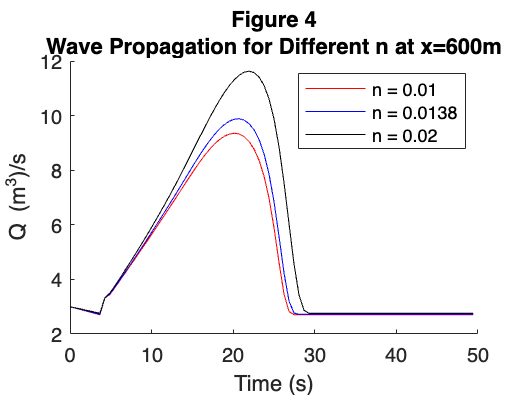

QVec = [];
S0 = 0.0005;
dt = 0.61;
for n = [.01 .0138 .02]
    [Q, t] = waveProp(S0,n, dt);
    QVec = [ QVec; Q(7,:)];
end

figure 
hold on
plot(t, QVec(1,:), 'r')
plot(t, QVec(2,:), 'b')
plot(t, QVec(3,:), 'k')
xlabel('Time (s)');
ylabel('Q (m^3)/s');
title(["Figure 4", "Wave Propagation for Different n at x=600m"]);
legend('n = 0.01', 'n = 0.0138', 'n = 0.02');

## Discussion

For the simulation in Figure 4, the *n* parameter (Manning's roughness coefficient) was altered to be 0.01 and 0.02 in addition to the original value of 0.0138. The relationship found was the bigger the *n* value, the higher the peak discharge. This makes sense because channel roughness inhibits the flow of water. Therefore, a channel that is rougher could have a "backwater effect," leading to a buildup of upstream water, which could result in increased discharge.

## Results

*What simulations did you run with the model?*

*Describe the results.*

*How do the results compare with any known solutions, or data?*

*How do the results change with different methods, time steps, grid spacing, or model parameters?*

*What did the model tell you about the process you were studying?*

*How could the model be improved in terms of methods used or processes included?*

An assumption made in our parameter determination method was the representation of the river cross-section as rectangular. Although this simplification serves its purpose reasonably well, it is acknowledged that a trapezoidal representation would align more closely with the natural shape of rivers. Incorporating a trapezoidal method could enhance the accuracy of our model, providing a more realistic depiction of real-world river geometries.

Also, our n variable, channel roughness, could be varied spatially. Real world river systems have varying roughness of channel due to vegetation and sediment transport.

## References

A. Osman Akan, and Ben Chie Yen. “Diffusion-Wave Flood Routing in Channel Networks.” *Journal of the Hydraulics Division*, vol. 107, no. 6, 1 June 1981, pp. 719–732, [https://doi.org/10.1061/jyceaj.0005681](https://doi.org/10.1061/jyceaj.0005681). Accessed 5 Dec. 2023.

B. A. Sulistyono, and L H Wiryanto. “Investigation of Flood Routing by a Dynamic Wave Model in Trapezoidal Channels.” *Nucleation and Atmospheric Aerosols*, 1 Jan. 2017, [pubs.aip.org/aip/acp/article/1867/1/020020/972827/Investigation-of-flood-routing-by-a-dynamic-wave](http://pubs.aip.org/aip/acp/article/1867/1/020020/972827/Investigation-of-flood-routing-by-a-dynamic-wave), [https://doi.org/10.1063/1.4994423](https://doi.org/10.1063/1.4994423). Accessed 5 Dec. 2023

Chagas, Patrícia, and Raimundo Souza. “Solution of Saint Venant’s Equation to Study Flood in Rivers, through Numerical Methods.” 2005.

Keskin, M.Erol, and Necati Aǧiralioǧlu. “A Simplified Dynamic Model for Flood Routing in Rectangular Channels.” *Journal of Hydrology*, vol. 202, no. 1-4, Dec. 1997, pp. 302–314, [https://doi.org/10.1016/s0022-1694(97)00072-3](https://doi.org/10.1016/s0022-1694(97)00072-3). Accessed 15 Nov. 2022.

Mujumdar, P.P. Flood wave propagation. Reason 6, 66–73 (2001). [https://doi.org/10.1007/BF02839085](https://doi.org/10.1007/BF02839085)

## Simulation Function

function [Q, t] = waveProp(S0, n, dt)
L = 2000;
b = 5;
g = 9.8;
h = 3.5;

%set up time and space vectors
t = 0:dt:50; 
dx = 100;
x = 0:dx:L;

% Pre-allocate Q matrix and A matrix
% Discharge (Q) matrix:
Q = zeros(length(x), length(t));
% set up boundary conditions for Q
Q0 = 3;
Qp = 12;
tp = 10;
tb = 20;
mask = t < 10;
Q(1,mask) = Q0 + ((Qp-Q0)/(tp))*t(mask);
Q(:, 1) = Q0;
mask = t >= 10 & t < 20; 
Q(1,mask) = Q0 - ((Qp-Q0)/(tb-tp))*(t(mask)-tb);
mask = t >= 20;
Q(1,mask) = Q0;
% Cross Section Area (A) matrix:
A = ones(length(x), length(t));
A(:,1) = b*h;
% matrix with the same dimensions to keep track of Courant value
C = zeros(length(x), length(t));

%solve the equations
for j = 1:length(t)-1
    for i = 2:length(x)-1 
        R = A(i,j)/(2*h+b);
        alpha = 2*(Q(i,j)/A(i,j)) + (((g*A(i,j))/b)+(Q(i,j)/A(i,j))^2)/((Q(i,j)/A(i,j))*((5/3)-(4/3)*(R/b)));
        beta = g*A(i,j)*(((Q(i,j)^2*n^2)/(A(i,j)*R^(4/3)))-S0);
       
        C(i,j) = (dt/dx) * alpha;

        Q(i, j+1) = Q(i,j) - (dt/dx) * alpha * (Q(i,j)-Q(i-1,j)) + beta*dt;
        A(i, j+1) = A(i,j) - (dt/dx) * (Q(i, j+1)-Q(i-1,j+1));
    end
end
end